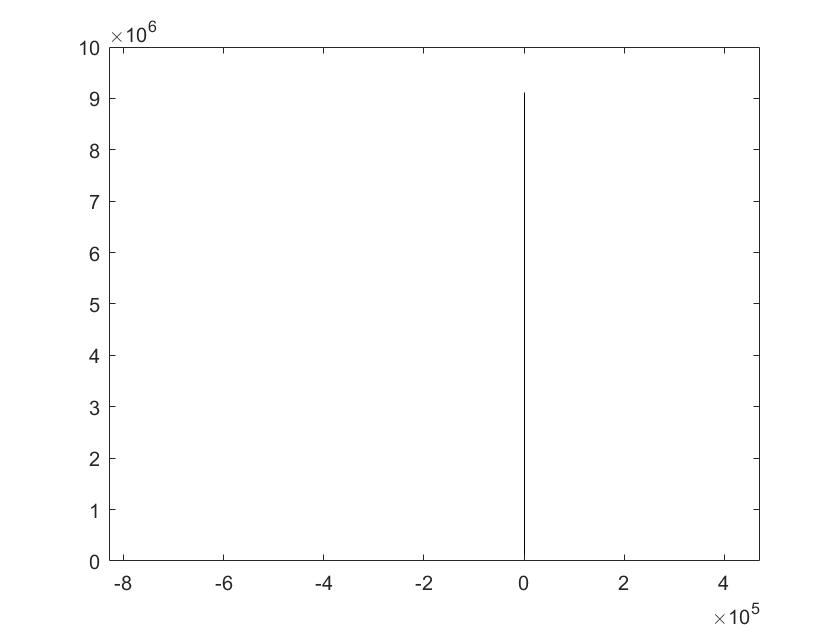

clear
beta_0=0;
beta_1=1;
sigma_x=1;
sigma_y=1;
x_star=[1 2 3 4];

num=10e6;
n=4;

y_star=beta_0+beta_1*x_star;
x=sigma_x*randn(num,n)+x_star;
y=sigma_y*randn(num,n)+y_star;

mx=mean(x,2);
my=mean(y,2);

Sxx=1/(n-1)*sum(((x-mx).*(x-mx)),2);
Syy=1/(n-1)*sum(((y-my).*(y-my)),2);
Sxy=1/(n-1)*sum(((x-mx).*(y-my)),2);

beta_1_hat=(Syy-Sxx+sqrt((Syy-Sxx).*(Syy-Sxx)+4*Sxy.*Sxy))./(2*Sxy);
beta_0_hat=my-mx.*beta_1_hat;
x_hat=x+beta_1_hat.*(y-beta_0_hat-x.*beta_1_hat)./(beta_1_hat.*beta_1_hat+1);
sigysq=1/(num-1)*sum(((y-y_star).*(y-y_star)),2);
sigxsq=1/(num-1)*sum(((x-x_star).*(x-x_star)),2);

histogram(beta_1_hat)

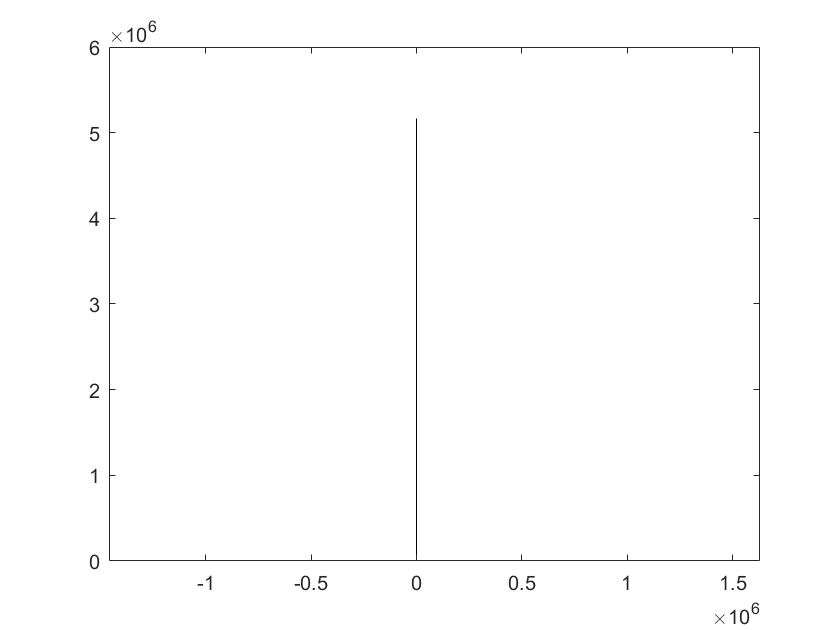

histogram(beta_0_hat)

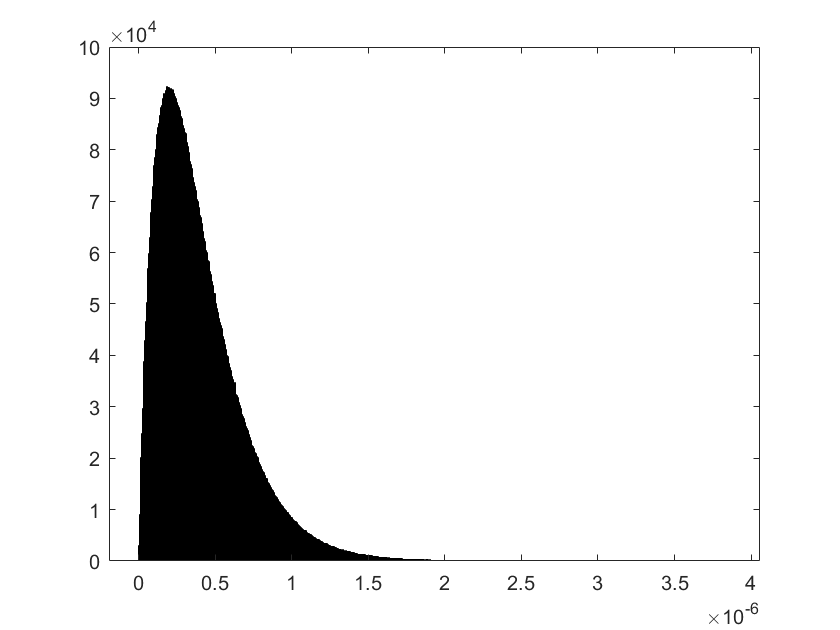

histogram(sigxsq)

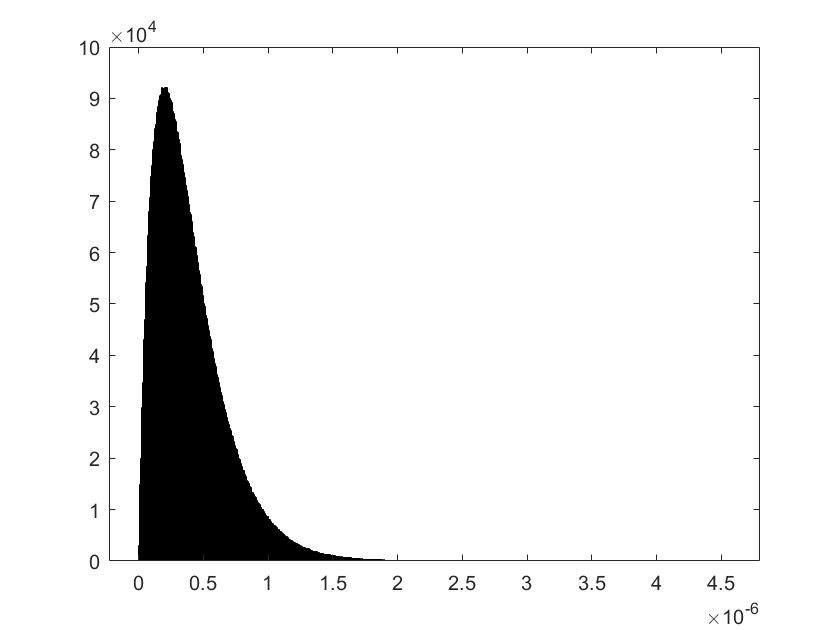

histogram(sigysq)

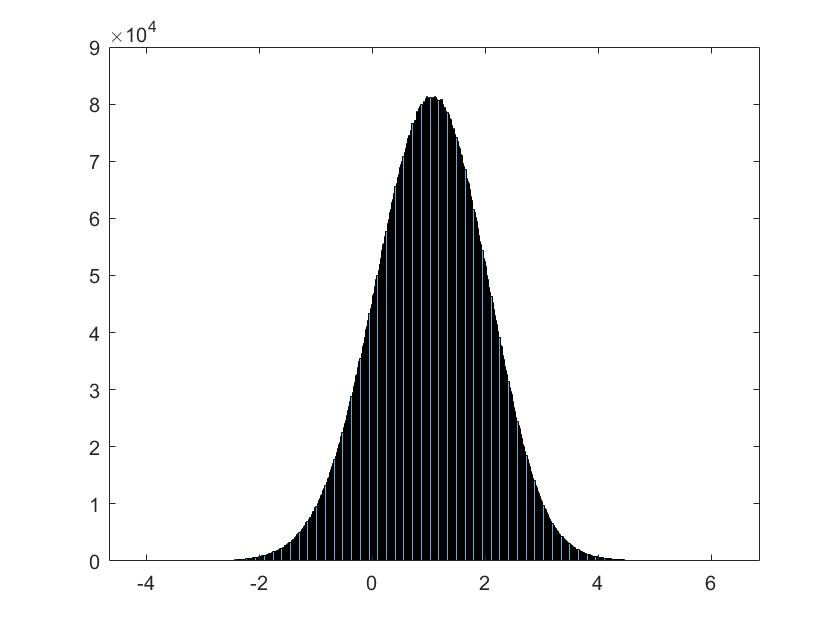

histogram(x_hat(:,1))

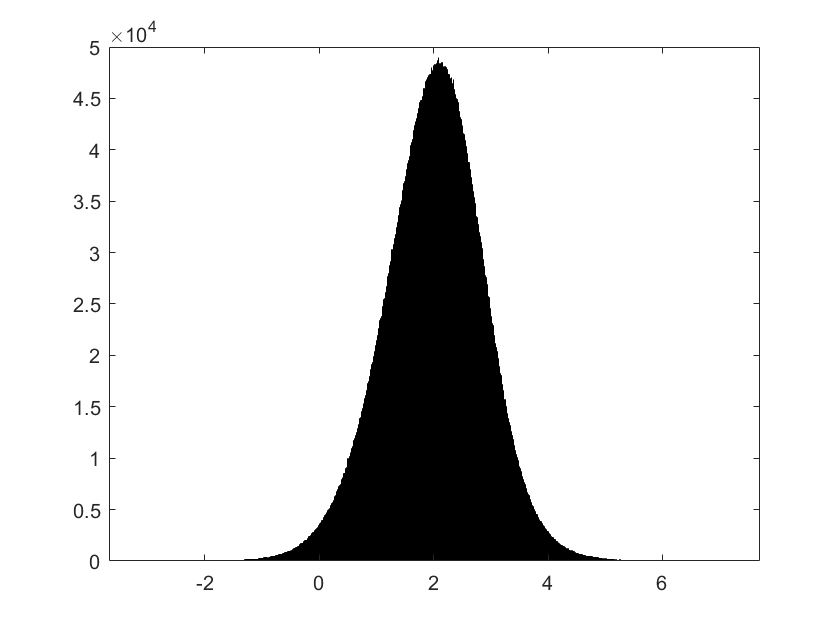

histogram(x_hat(:,2))

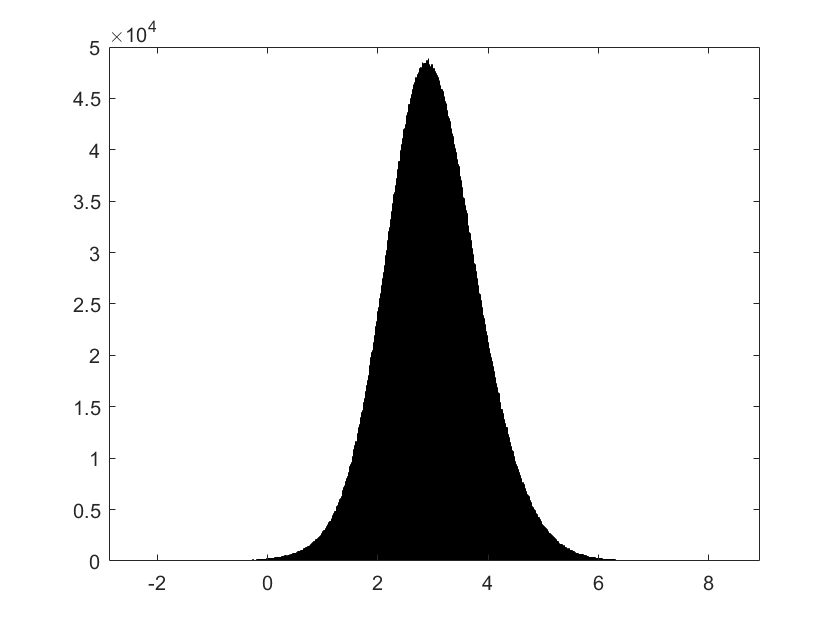

histogram(x_hat(:,3))

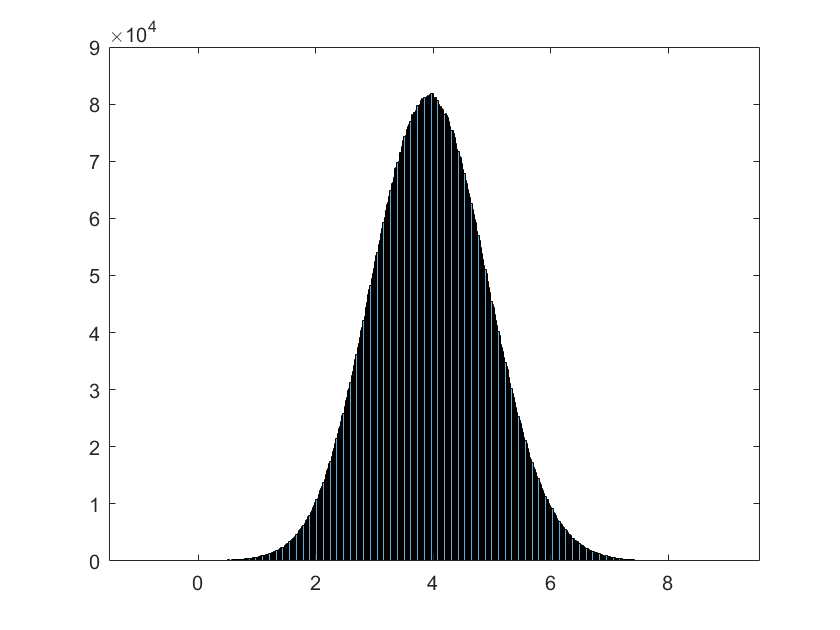

histogram(x_hat(:,4))


Mean_sigmaysq=mean(sigysq)

Mean_sigmaysq = 4.0005e-07

Mean_sigmaxsq=mean(sigxsq)

Mean_sigmaxsq = 4.0002e-07

Mean_beta_0_hat=mean(beta_0_hat)

Mean_beta_0_hat = -0.5841

Mean_beta_1_hat=mean(beta_1_hat)

Mean_beta_1_hat = 1.2063

Mean_x=mean(x_hat',2)

Mean_x =     1.0404
    2.0135
    2.9869
    3.9595



Var_sigmaysq=var(sigysq)

Var_sigmaysq = 8.0000e-14

Var_sigmaxsq=var(sigxsq)

Var_sigmaxsq = 7.9983e-14

Var_beta_0=var(beta_0_hat)

Var_beta_0 = 1.0336e+06

Var_beta_1=var(beta_1_hat)

Var_beta_1 = 1.7394e+05

Var_x_hat=var(x_hat)

Var_x_hat =     0.9540    0.7433    0.7433    0.9528


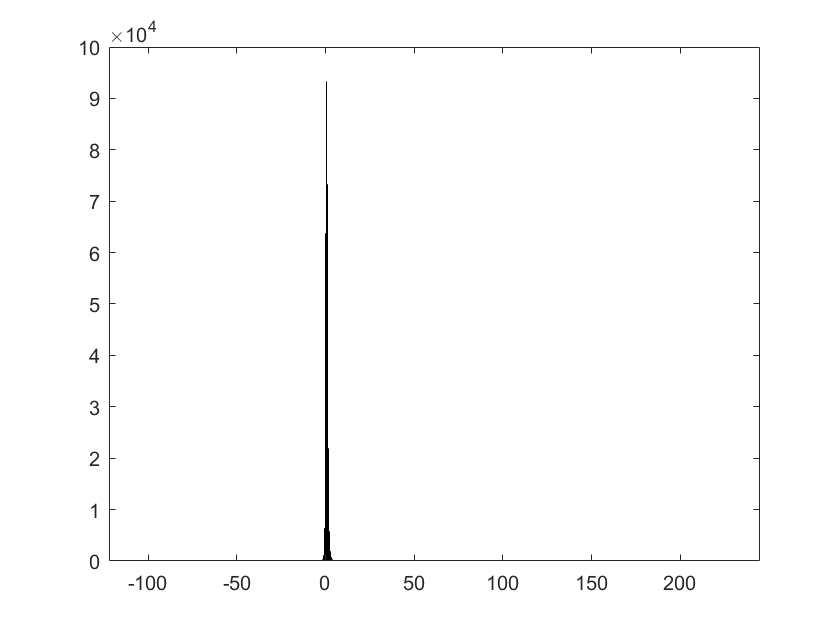


B1O=Sxy./Sxx;
B0O=my-mx.*B1O;
x_h=x+B1O.*(y-B0O-x.*B1O)./(B1O.*B1O+1);
sy=1/(num-1)*sum(((y-y_star).*(y-y_star)),2);
sx=1/(num-1)*sum(((x-x_star).*(x-x_star)),2);

histogram(B1O)

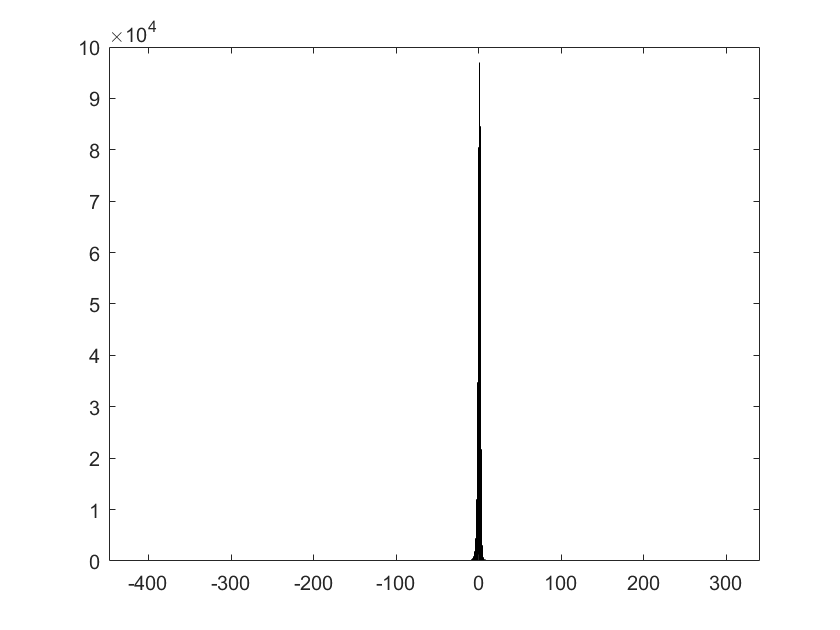

histogram(B0O)

histogram(sy)

histogram(sx)

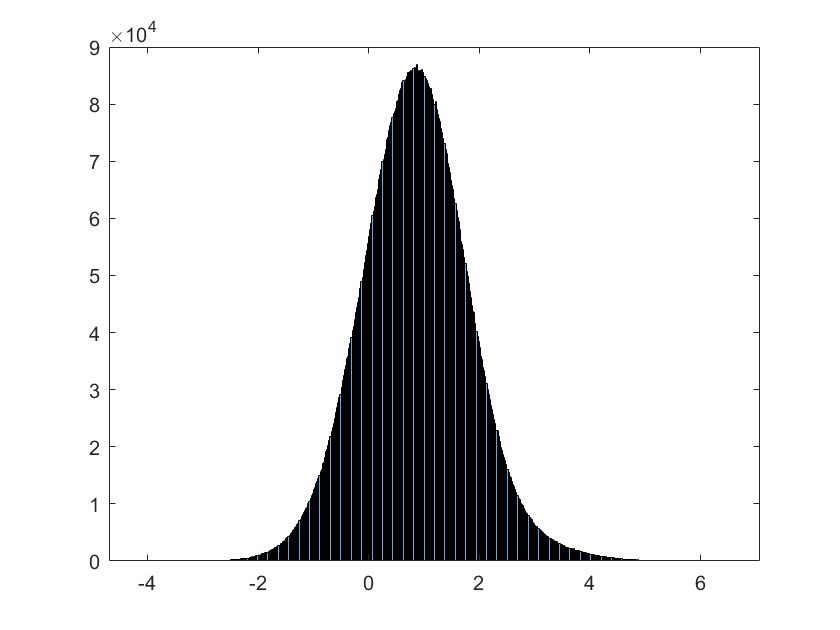

histogram(x_h(:,1))

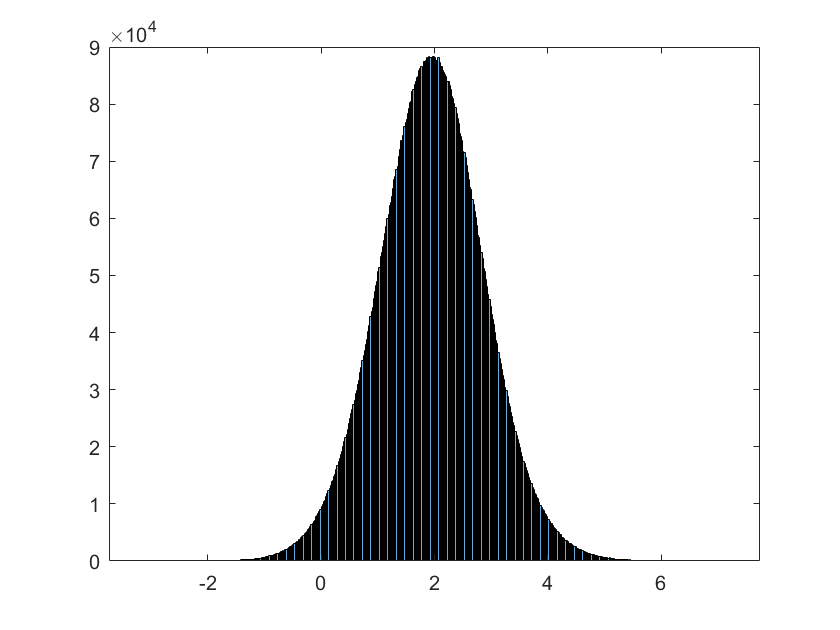

histogram(x_h(:,2))

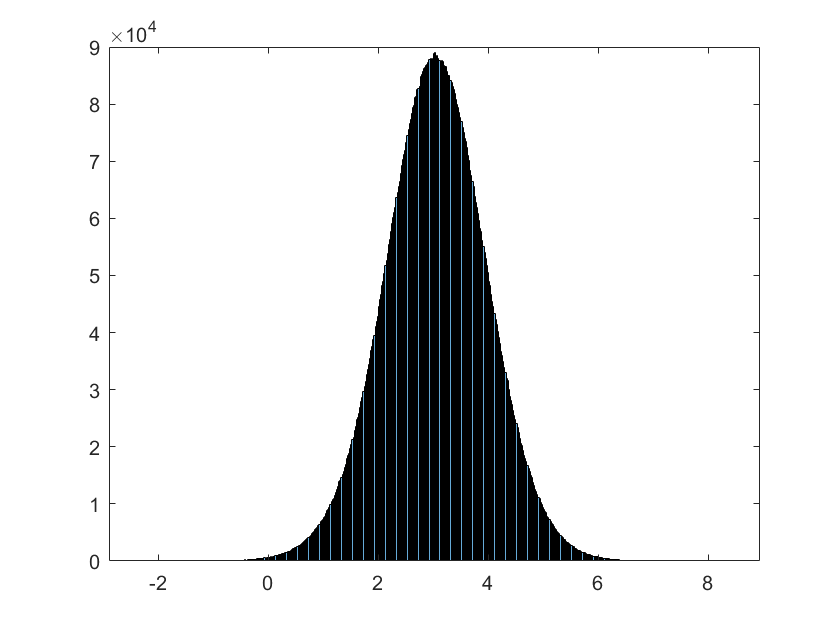

histogram(x_h(:,3))

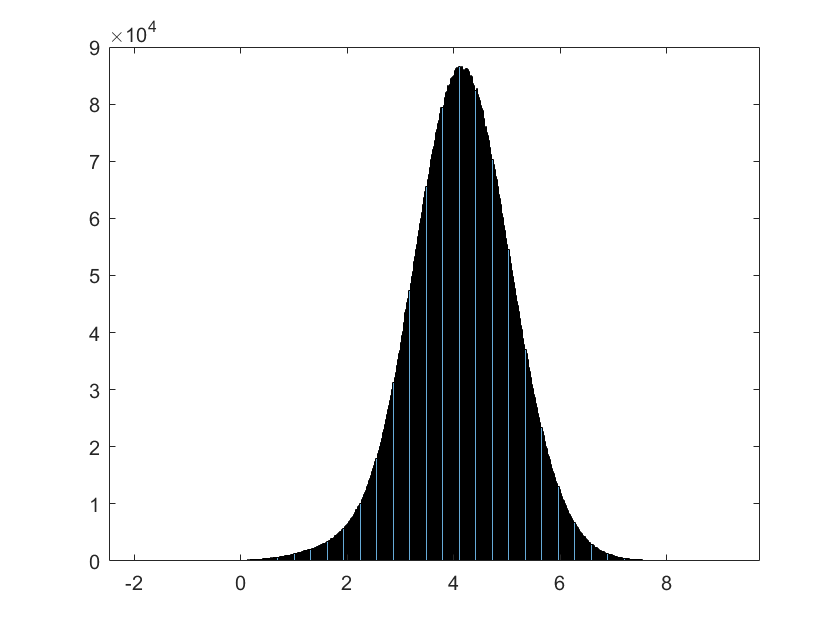

histogram(x_h(:,4))


Mean_sy=mean(sy)

Mean_sy = 4.0005e-07

Mean_sx=mean(sx)

Mean_sx = 4.0002e-07

Mean_B0O=mean(B0O)

Mean_B0O = 0.6398

Mean_B1O=mean(B1O)

Mean_B1O = 0.7439

Mean_x_h=mean(x_h',2)

Mean_x_h =     0.8575
    1.9526
    3.0477
    4.1424



Var_sy=var(sy)

Var_sy = 8.0000e-14

Var_sx=var(sx)

Var_sx = 7.9983e-14

Var_B0O=var(B0O)

Var_B0O = 3.2683

Var_B1O=var(B1O)

Var_B1O = 0.4447

Var_x_h=var(x_h)

Var_x_h =     0.9300    0.8623    0.8624    0.9293
